# Getting Started with the Switched Mode Power Supply Toolbox

## Description

The Switched Mode Power Supply Toolbox provides capabilities for the steady-state and small-signal modeling of switched mode power supplies.  These capabilities facilitate design optimization in power electronics for a variety of applications.  

## System Requirements

The toolbox is tested with MATLAB R2022b and after.  Known issues will occur with MATLAB versions prior to R2020b.  

The following software is **not** required, but is used if present to enhance toolbox capabilities

*Optional Software:*

- PLECS: for schematic entry and circuit parsing, PLECS can be used.  If PLECS is not available, SPICE netlist files may be used.  PLECS is a paid software tool: [https://www.plexim.com/products/plecs](https://www.plexim.com/products/plecs)

- Ghostscript: for datasheet digitization, the free tool ghostscript is used to convert pdf pages into image files.  If ghostscript is not installed, datasheet digitization through the built-in app will not be available. [https://ghostscript.com/releases/gsdnld.html](https://ghostscript.com/releases/gsdnld.html)

- Computer Vision and Image Processing Toolboxes:  These MATLAB toolboxes are used to enhance the performance of the datasheet digitization app.  The app will function without these toolboxes, with reduced performance

## Structure and Use

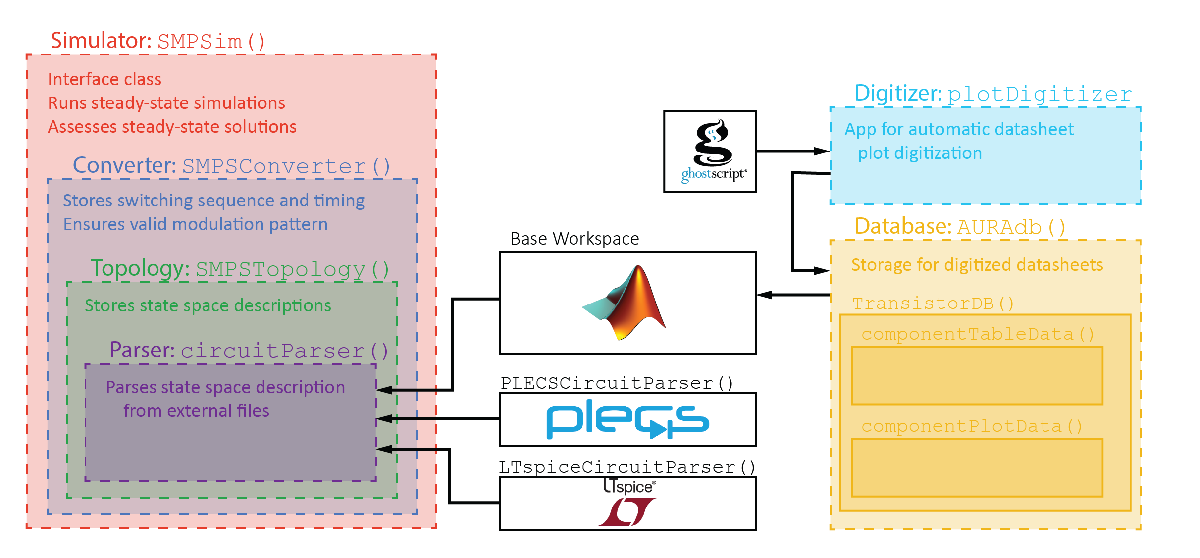

#### Switched Mode Power Supply Simulation

The toolbox is structured with class wrappers to manage data access and manipulation.  At the top level, the `SMPSim()` class implements a Switched Mode Power Supply steady-state simulation.  Most interactions with the toolbox occur through this class.  The SMPSim() class contains references internally to `SMPSConverter()` and `SMPSTopology()` classes that, respectively, generate/store the modulation pattern and state space description of the converter.  `CircuitParser()` class objects interface wither PLECS circuits (via simulink) or LTSpice netlists as a means of defining the converter circuit.  

#### Discrete Component Repository

The` AURAdb() `class implements a database for power electronics discrete components.  Components contain table data, digitized plots, and methods to access and manipulate this data.  An additional app, `plotDigitizer`, assists in digitizing plots directly from datasheets.  

#### Switched Mode Power Supply Design Optimization

The simulation, with or without the component repository is constructed to allow design iteration and optimization from within MATLAB.  From either PLECS or LTSpice, the toolbox allows variable parameterization of components and converter characteristics.  When a parameter of the schematic is defined with a variable name, rather than a numerical quantity or local expression, the toolbox evaluates the parameter in the MATLAB base workspace.  For example, if a schematic denotes a transistor on resistance as "`Ron1`" and does not define this value in the netlist/PLECS circuit, the toolbox will use the current value of the variable `Ron1` from the MATLAB base workspace.  This facilitates design optimization by allowing MATLAB to redefine circut parameters during the execution of a loop.  The same is true of modulation parameters, though these should be explicitly altered by the methods of the `SMPSim()` class.

## Attribution

If the framework provided in this toolbox is used in preparation of a published work in a manner warranting a citation, the following is the suggested refernece format for the toolbox itself

D. Costinett, Switched Mode Power Supply Toolbox,  https://github.com/costinet/AURA

Select aspects of the framework are detailed in the following publicaitons

- J. A. Baxter and D. J. Costinett, "Power Converter and Discrete Device Optimization Utilizing Discrete Time State-Space Modeling," 2023 IEEE 24th Workshop on Control and Modeling for Power Electronics (COMPEL), Ann Arbor, MI, USA, 2023, pp. 1-8, doi: 10.1109/COMPEL52896.2023.10221030.

- J. A. Baxter and D. J. Costinett, "Broad-Scale Converter Optimization Utilizing Discrete Time State-Space Modeling," 2022 IEEE Design Methodologies Conference (DMC), Bath, United Kingdom, 2022, pp. 1-6, doi: 10.1109/DMC55175.2022.9906473.

- J. A. Baxter and D. J. Costinett, "Steady-State Convergence of Discrete Time State-Space Modeling with State-Dependent Switching," 2020 IEEE 21st Workshop on Control and Modeling for Power Electronics (COMPEL), Aalborg, Denmark, 2020, pp. 1-8, doi: 10.1109/COMPEL49091.2020.9265734.

- J. A. Baxter and D. J. Costinett, "Converter Analysis Using Discrete Time State-Space Modeling," 2019 20th Workshop on Control and Modeling for Power Electronics (COMPEL), Toronto, ON, Canada, 2019, pp. 1-8, doi: 10.1109/COMPEL.2019.8769686.

## Licensing

`MIT License`

`Copyright (c) [2020] [Daniel Costinett]`

`Permission is hereby granted, free of charge, to any person obtaining a copy of this software and associated documentation files (the "Software"), to deal in the Software without restriction, including without limitation the rights to use, copy, modify, merge, publish, distribute, sublicense, and/or sell copies of the Software, and to permit persons to whom the Software is furnished to do so, subject to the following conditions:`

`The above copyright notice and this permission notice shall be included in all copies or substantial portions of the Software.`

`THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY, FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE SOFTWARE.`

# Examples

## Add test circuits folder to the path

This block makes sure that the directories containing example PLECs and LTSpice files are in the path so that they are available throughout the script.

sdir = fileparts(matlab.desktop.editor.getActiveFilename);

ts = 1.0e-06 *

    0.2500    0.0050    0.7400    0.0050


Gd0 = 85.3333

w0 = 1.0607e+05

addpath(sdir);
addpath('testConverters\ExampleTopologies')
addpath('testConverters\LTspice NetLists')

## Steady-State Solve from PLECS circuit

To have self-contained examples, the PLECS circuit is embedded in a simulink file that defines all necessary variables for simulation.  The `loadSimulinkOutputsToBase` function loads all these variables from the simulink file into the base workspace so that they are available to PLECS.  Be careful that this could overwrite pre-exisitng varibles in the base workspace.

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
loadSimulinkOutputsToBase(modelfile,PLECsModel);    %Per the file format, all the necessary 
                                                    % variables are defined in simulink and loaded into the base workspace 
circuitPath = [modelfile '/' PLECsModel];

`SMPSim` initializes the model, including embedded `SMPSconverter` and `SMPStopology classes`, taking the required details of the circuit from the model file given by `circuitPath`, and pulling additional parameters of circuit components and modulation scheme from the base workspace

sim = SMPSim();
sim.initialize(circuitPath);        %swvec, us, and ts are defined in the simulink file and
                                    %loaded via loadSimulinkOutputsToBase
                                    %They will be pulled from the base workspace

The `steadyState` function solves the converter's steady-state solution without considering any state-dependent switching.  For e.g. synchronous converters with no deadtime modeled, this is sufficient.  For converters where diode conduction will (or may) be present, additional steps are needed for a valid solution.  

sim.steadyState();

`plotAllStates(1)` plots all of the states ***x***(*t*) as continuous waveforms over one switching period, in figure 1.  The second line does the same for the outputs ***y***(*t*) in figure 2.

sim.plotAllStates(1)
sim.plotAllOutputs(2)

## Steady-State Solve from LTspice netlist

This section follows the above, but instead using an LTspice file for the converter definition.  The LTspice file follows standard SPICE netlist formatting, but includes additional lines

        .param ts = [1u 50n 1u 50n]

        .param swvec = [1 0 0 0; 0 0 0 0; 0 1 0 0; 0 0 0 0]

which defined the switching times and states.  Like the above case, these will be loaded into the base workspace and can be overwritten later to change their values or, if they are not included in the netlist, can be originally provided from the base workspace.

modelfile = 'BuckTest1.net';

sim = SMPSim();
sim.initialize(modelfile);                      %swvec, us, and ts are defined 
                                                %in the netlist file and
                                                %loaded during parsing
sim.steadyState();
sim.plotAllStates(3)
sim.plotAllOutputs(4)


## Steady-State Solve from PLECS circuit with dependent States

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';
loadSimulinkOutputsToBase(modelfile,PLECsModel);
circuitPath = [modelfile '/' PLECsModel];
sim = SMPSim();

initialize can be called with explicitly-defined switching states `swvec`, inputs `us`, and switching times `ts`.

sim.initialize(circuitPath, swvec, us, ts);     % here swvec, us, and ts are explicitly specified

As before, `steadyState` solves the solution without considering dependent states.  In this case, diode conduction needs to be accounted for in the steady-state solution.  The `hold` command makes sure subsequent call to `plotAllStates` doesn't clear the subplots so that each solution can be compared.

sim.steadyState();
sim.plotAllStates(5);               %Plot all states BEFORE solving valid diode conduction
hold(gcf().Children,'on');          %hold on, to compare with final solution

findValidSteadyState attempts to solve correct dependent state switching by, alternately, algorithmic determination of switching states and time adjustment based on an error minimization.

sim.findValidSteadyState();         %solves correct dependent state behaviour
sim.plotAllStates(5)                %Plot all states AFTER solving valid diode conduction

## Steady-State Solve from LTspice netlist with dependent States

modelfile = 'BuckTest1.net';

sim = SMPSim(modelfile);            %Rather than calling initialize() separately, the same effect is 
                                    %obtained by calling the constructor
                                    %with a file path reference


sim.plotAllStates(6);               %Plot all states BEFORE solving valid diode conduction
hold(gcf().Children,'on');          %hold on, to compare with final solution

sim.findValidSteadyState();         %solves correct dependent state behaviour
sim.plotAllStates(6)                %Plot all states AFTER solving valid diode conduction


## Example Underdefined PLECS File

If insufficient model details are available in the supplied model and/or the base workspace to fully define the converter topology, and error is thrown which details the missing information.  These variables can be defined in the base workspace programatically, or included in the simulation file explicitly.  The file `DAB_Incomplete `has many elements defined with variable names that are not given scalar values in the base workspace.

modelfile = 'DAB_Incomplete'; PLECsModel = 'DAB_oneCap';

open_system(modelfile,'loadonly');
circuitPath = [modelfile '/' PLECsModel];
    
sim = SMPSim();
conv = sim.converter;
top = sim.topology;
    
try
    top.loadCircuit(circuitPath); %This fails with explanation of missing variables
catch e
    disp(getReport( e, 'extended', 'hyperlinks', 'on' ) )
end

## Finding signals in simulation class

The SMPSim object can be initialized without a switching scheme or inputs.  This is often useful as an intermediate step to determine the locations of e.g. input signals in the input vector ***u ***or switches in the binary switching state vector `swvec.  `This code shows both how to view these assignments in the `stateNames` and other names properties of the `SMPSim` object, and hwo to programatically find a signal's index in the appropriate vector with the `sigLoc` function.

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';

circuitPath = [modelfile '/' PLECsModel];

sim = SMPSim(circuitPath);       %here swvec, us, and ts are not defined, so no switching states will be produced
                                 %but, the circuit can be parsed to look at
                                 %the switch vector, and arrangement of signals in x,u,y

states = sim.stateNames               %Show signal assignment in the state vector                              
CoutLoc = sim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x

switches = sim.switchNames             %Show switch arrangement for swvec

inputs = sim.inputNames               %Show signal assignment in input vector
VdcLoc = sim.sigLoc('V_dc','u');    %Location of Vdc's voltage in the input vector, u

outputs = sim.outputNames              %Show signal assignment in output vector
VdsLoc = sim.sigLoc('FET:Vm','y');  %Location of FETs Vds voltage in the output vector, y


## Getting Discrete Sampling Points

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';

loadSimulinkOutputsToBase(modelfile,PLECsModel);
circuitPath = [modelfile '/' PLECsModel];

sim = SMPSim(circuitPath, swvec, us, ts);   %here swvec, us, and ts are explicitly specified

sim.findValidSteadyState();         %solves correct dependent state behaviour

The `Xs`, `Ys`, and `YsEnd` properties of the SMPSim class give the states and outputs at each of the switching interfaces from the previous steady-state solution.  For a simulation with *ns* states, *nt* time intervals, and *no* outputs, these arrays have sizes

- Xs: *ns* x (*nt*+1) *note*: the first and last column of Xs are the same, as they are the states at *t*=0 and *t*=*Ts*, which are identical in periodic steady-state

- Ys: *no* x (*nt*+1)

- YsEnd: *no* x (*nt*+1)

States cannot change instantaneously, so they will always be continous across the switching boundary.  Outputs, however, are not guaranteed continuous, so both `Ys` and `YsEnd` are included.  `Ys` gives the outputs at the start of each swithcing interval, and `YsEnd` gives the outputs at the end of each subinterval

Xss = sim.Xs;                       % Get state vector at each switching interface
Yss = sim.Ys;                       % Get output vector at each switching interface
YssE = sim.YsEnd;                   % Get output vector at each switching interface before switching occurs

As a further application example, the following finds the Vds of each FET in the circuit just before turning on, and the channel current just before turning off.

FETLoc = sim.sigLoc('FET','sw');
IdsLoc = sim.sigLoc('FET:Am','y');
VdsLoc = sim.sigLoc('Coss','x');

switchingActions = diff([ sim.swvec(end,:); sim.swvec],1);  %Looks at when switching states change
FEToffInt = find(switchingActions(:,FETLoc) == -1); %Find when FET switches off
FETonInt = find(switchingActions(:,FETLoc) == 1); %Find when FET switches on


FET_VdsOn = Xss(VdsLoc, FETonInt)               %Find FET Vds at turn-on instant 
FET_Ioff = YssE(IdsLoc,FEToffInt-1)             %Find FET Ids at turn-off instant (look at end of previous interval to apply correc C and D matrices)

## Averaging Signals in Steady-State

modelfile = 'BuckTest1.net';

sim = SMPSim(modelfile);                  

sim.findValidSteadyState();         %solves correct dependent state behaviour

The ssAvgs function averages all states and outputs over one full switching period for the current steady-state solution.

[avgXs, avgYs] = sim.ssAvgs();     %Get average values of all states and outputs in steady-state

The `avgXs` and `avqYs` signals are arranged the same as `Xs` and `Ys`, so can be indexed directly ot indices can be found with `sigLoc` 

VoutLoc = sim.sigLoc('C1','x');     %Location of Cout's voltage in the state vector, x
ILLoc = sim.sigLoc('L1','x');       %Location of L's current in the state vector, x
VgLoc = sim.sigLoc('V1','u');       %Location of Input voltage in the input vector, u
IgLoc = sim.sigLoc('Im_Ig','y');    %Location of Input current in the output vector, y

Pout = avgXs(VoutLoc)*avgXs(ILLoc); %Output power approximated (for small ripple)
Pin = sim.u(VgLoc)*avgYs(IgLoc);    %Exact average input power for constant Vg

eta = Pout/Pin*100

## Plotting Specific Signals

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';

loadSimulinkOutputsToBase(modelfile,PLECsModel);
circuitPath = [modelfile '/' PLECsModel];

sim = SMPSim(circuitPath, swvec, us, ts);     %here swvec, us, and ts are explicitly specified

sim.findValidSteadyState();         %solves correct dependent state behaviour

VoutLoc = sim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x
ILLoc = sim.sigLoc('L1','x');       %Location of L's current in the state vector, x

`plotAllStates` be default plots all states, but the optional second argument is an array of indices into Xs that specifies which signals to plot.  The same is possible with `plotAllOutputs.`

sim.plotAllStates(1,[CoutLoc ILLoc]);   %Plot just IL and Vout

## Getting Full Steady-State Waveforms

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';

loadSimulinkOutputsToBase(modelfile,PLECsModel);
circuitPath = [modelfile '/' PLECsModel];

sim = SMPSim(circuitPath, swvec, us, ts);     %here swvec, us, and ts are explicitly specified

sim.findValidSteadyState();         %solves correct dependent state behaviour

VoutLoc = sim.sigLoc('Cout','x');   %Location of Cout's voltage in the state vector, x
ILLoc = sim.sigLoc('L1','x');       %Location of L's current in the state vector, x

The` SS_WF_Reconstruct() `method is used inside the previous `plotAllStates` and `plotAllOutputs` methods.  It expands the discrete time model into a high resolution time series.  An additional input argument to the `SS_WF_Reconstruct() `function can be used to control the number of points in the reconstructed waveforms.

[xs, t, ys] = sim.SS_WF_Reconstruct();  %expands full-period time waveforms of states and outputs

Ilrms = sqrt(1/t(end)*trapz(t,xs(ILLoc,:)))

## Variable Input u

The file loaded in this example has the circuit structure shown below.  This can be interpreted as a wireless power transfer converter with coupled coils given by M2.  Here, the rectifier is implemented with switching devices, but no inverter is included.  Instead, the intention is to implement a squarewave voltage source Vg.  

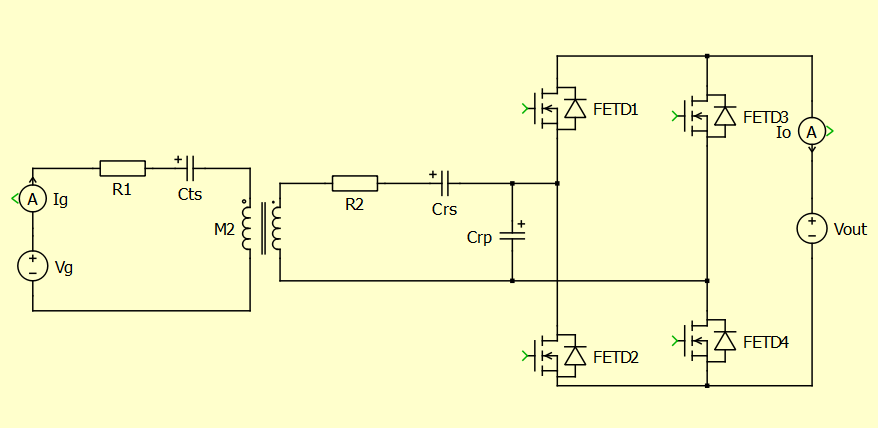

Because the value of the input voltage will show up in the input vector u of the state space description, its value can be changed between discrete intervals.  

modelfile = 'WPT_varyingU'; PLECsModel = 'WPT_SSP';
circuitPath = [modelfile '/' PLECsModel];

loadSimulinkOutputsToBase(modelfile,PLECsModel);

sim = SMPSim(circuitPath);

In this example, u is defined in the simulink file as 

`u= cat(3, [48; 24], [48; 24], [48; 24], [0;24], [-48; 24] , [-48; 24], [-48; 24], [0;24])`

where the input voltage varieds between +/- 48V over the period, and the output dc voltage is always 24V.  The third dimension of the structure is the time interval, corresponding to the timing vector `ts`.

disp(squeeze(sim.u))    %squeeze used to elimate the third dimension for display

sim.findValidSteadyState
sim.plotAllStates(10)
sim.plotAllOutputs(11)

# Experimental

## Small signal Models

Discrete time small-signal modeling is well-established.  Given that the circuits are already in suitable form, the `findSSTF()` method finds the transfer function from perturbations to any single time interval to all states at the end of the switching period.  

modelfile = 'AsyncBoost'; PLECsModel = 'Boost_Async';

loadSimulinkOutputsToBase(modelfile,PLECsModel);
circuitPath = [modelfile '/' PLECsModel];

% Convert boost to small-ripple for comparison to average model
Lf = Lf*100;
Ts = 1e-6;
Coss = 10e-12;
Cd = 10e-12;
ts = [Ts/4, 5e-9, Ts*(3/4)-10e-9, 5e-9]

sim = SMPSim(circuitPath, swvec, us, ts);     %here swvec, us, and ts are explicitly specified

sim.findValidSteadyState();         %solves correct dependent state behaviour

Gz = sim.findSSTF(1);               %solves transfer function from time interval 1 to all states at the end of the period

VoutLoc = sim.sigLoc('Cout','x');

bode(Gz(VoutLoc)*Ts)                %Multiplied by Ts to go from time->duty cycle
hold on;


The below constructs a traditional averaged model of a lossless Boost converter for comparison.  Given the small-ripple design, the discrete time model should match well up to frequencies approaching the Nyquist rate

% Average model of lossless Boost for comparison
s = tf('s');
D = ts(1)/sum(ts);
V = Vg/(1-D);
Gd0 = V/(1-D)
w0 = (1-D)/sqrt(Lf*Co)
Q = (1-D)*RL*sqrt(Co/Lf);
wz = (1-D)^2*RL/Lf;
Gvd = Gd0*(1-s/wz)/(1+s/Q/w0 + (s/w0)^2);

P = bodeoptions;
P.PhaseMatching = 'on';
bode(Gvd,P)
legend('Discrete Time', 'Average Model','Location','southWest');

## Component Database

Adb = AURAdb();
tdb = Adb.transistors;

tdb(8).datasheet;

Ron = tdb(8).ron.approx;
Coss = tdb(8).Coss.approx;

graphs = [tdb(8).graphs(:)];
CplotLoc = find(strcmp({graphs.yLabel}, 'Capacitance'),1,'last');
curveLoc = strcmp(graphs(CplotLoc).dataLabels, 'Coss');

CossV = graphs(CplotLoc).plotData{curveLoc};
plot(CossV(:,1),CossV(:,2));

## GUI for Datasheet digitization

sdir = fileparts(matlab.desktop.editor.getActiveFilename);

plotDigitizer([sdir '\resources\EPC2023_datasheet.pdf'])